# File Name: MATLAB_Basic_05_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

## Estimate Normals of Point Cloud

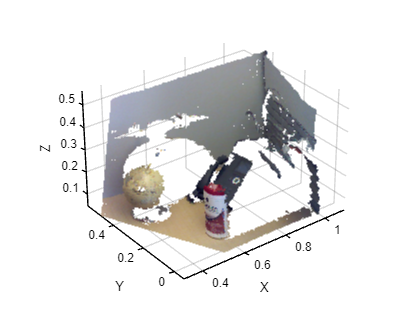

% Load a point cloud.
load('object3d.mat');

%%%%%%%%%% TODO %%%%%%%%%%
% Estimate the normal vectors.
normals = pcnormals(ptCloud);

figure
pcshow(ptCloud)
xlabel('X');
ylabel('Y');
zlabel('Z');
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])
hold on

## %%%%%%%%%% TODO %%%%%%%%%%

Get point cloud location and normal vector.

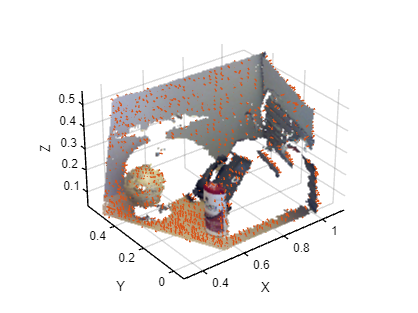

x = ptCloud.Location(1:10:end,1:10:end,1);
y = ptCloud.Location(1:10:end,1:10:end,2);
z = ptCloud.Location(1:10:end,1:10:end,3);

u = normals(1:10:end,1:10:end,1);
v = normals(1:10:end,1:10:end,2);
w = normals(1:10:end,1:10:end,3);

% Plot the normal vectors.
quiver3(x,y,z,u,v,w);
hold off

## %%%%%%%%%% TODO %%%%%%%%%%

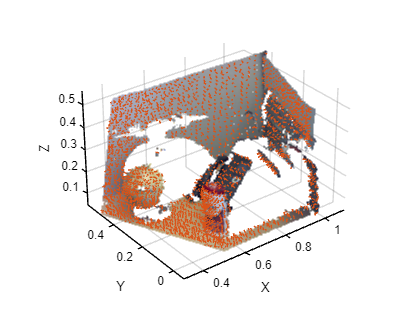

sensorCenter = [0,-0.3,0.3];
for k = 1 : numel(x)
    p1 = sensorCenter - [x(k),y(k),z(k)];
    p2 = [u(k),v(k),w(k)];
    % Flip the normal vector if it is not pointing towards the sensor.
    angle = atan2(norm(cross(p1,p2)),p1*p2');
    if angle > pi/2 || angle < -pi/2
        u(k) = -u(k);
        v(k) = -v(k);
        w(k) = -w(k);
    end
end

figure
pcshow(ptCloud)
xlabel('X');
ylabel('Y');
zlabel('Z');
set(gcf,'color','w');
set(gca,'color','w');
set(gca, 'XColor', [0. 0. 0.], ...
    'YColor', [0. 0. 0.], ...
    'ZColor', [0. 0. 0.])
hold on
quiver3(x, y, z, u, v, w);
hold off